
% Given parameters
f = 400;        % Signal frequency in Hz
A = 1;          % Amplitude
phi = 0;        % Phase in radians
fs = 4000;      % Sampling frequency in Hz
Ts = 1/fs;      % Sampling period in seconds

% Calculate theta
theta = 2*pi*(f/fs);

% Define the total time to cover two periods of the signal
T_signal = 1/f;            % Period of the signal
t_total = 2*T_signal;      % Total time for two periods

% Create a fine time grid for the continuous-time signal
dt = Ts / 10;              % Time step (10 times finer than Ts)
t = 0:dt:t_total;          % Time vector for continuous-time signal

% Generate the continuous-time signal x_c(t)
x_c = A * sin(2*pi*f*t + phi);

% Number of samples needed to cover t_total
N = round(t_total / Ts);   % Ensure integer number of samples
n = 0:N;                   % Sample indices

% Generate the discrete-time samples x[n]
x_n = A * sin(theta * n + phi);

% Corresponding time instances for the samples
t_n = n * Ts;

% Plotting
figure;
plot(t*1000, x_c, 'b', 'LineWidth', 1.5);  % Continuous-time signal in blue

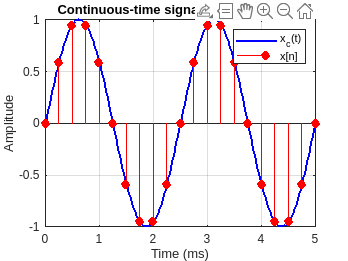

hold on;
stem(t_n*1000, x_n, 'r', 'filled');        % Discrete samples in red
xlabel('Time (ms)');
ylabel('Amplitude');
title('Continuous-time signal and its samples');
legend('x_c(t)', 'x[n]');
grid on;
hold off;

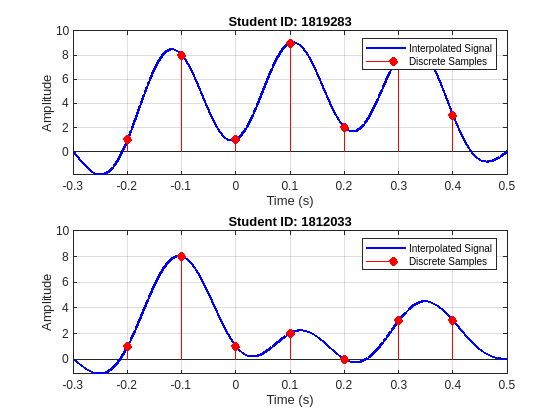

% Given parameters
T_s = 0.1;          % Inter-sample distance
start_ind = -2;     % Starting index

% Student IDs
studentid1 = 1819283;
studentid2 = 1812033;

% Encode the student IDs as vectors
x1 = [1 8 1 9 2 8 3];  % Student ID 1819283
x2 = [1 8 1 2 0 3 3];  % Student ID 1812033

% Perform sinc interpolation for Student ID 1
[x_a1, t1, n1] = sincinterpolation(x1, start_ind, T_s);

% Perform sinc interpolation for Student ID 2
[x_a2, t2, n2] = sincinterpolation(x2, start_ind, T_s);

% Plotting
figure;

% First subplot for Student ID 1
subplot(2,1,1);
plot(t1, x_a1, 'b', 'LineWidth', 1.5);      % Interpolated signal in blue
hold on;
stem(n1 * T_s, x1, 'r', 'filled');          % Discrete samples in red
grid on;
title('Student ID: 1819283');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Interpolated Signal', 'Discrete Samples');
hold off;

% Second subplot for Student ID 2
subplot(2,1,2);
plot(t2, x_a2, 'b', 'LineWidth', 1.5);      % Interpolated signal in blue
hold on;
stem(n2 * T_s, x2, 'r', 'filled');          % Discrete samples in red
grid on;
title('Student ID: 1812033');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Interpolated Signal', 'Discrete Samples');
hold off;

function [x_a, t, n] = sincinterpolation(x, start_ind, T_s)
    % SINCINTERPOLATION Interpolates a discrete-time signal using sinc interpolation.
    %   [x_a, t, n] = sincinterpolation(x, start_ind, T_s) interpolates the
    %   discrete-time signal x, starting from index start_ind with inter-sample
    %   distance T_s, and returns the interpolated analog signal x_a, the
    %   continuous-time axis t, and the discrete-time axis n.
    %
    % Inputs:
    %   x         - Discrete-time signal samples (vector)
    %   start_ind - Starting index of the sequence (integer)
    %   T_s       - Inter-sample distance (scalar)
    %
    % Outputs:
    %   x_a - Interpolated analog signal (vector)
    %   t   - Continuous-time axis (vector)
    %   n   - Discrete-time axis (vector)

    % Create the continuous-time axis t
    t = T_s * ((start_ind - 1):0.001:(start_ind + length(x)));
    
    % Create the discrete-time axis n
    n = start_ind:(start_ind + length(x) - 1);
    
    % Initialize the interpolated signal x_a
    x_a = zeros(size(t));
    
    % Loop over each sample in x to compute the interpolated signal
    for k = 1:length(x)
        % Compute the sinc function argument
        sinc_arg = (t / T_s) - n(k);
        
        % Accumulate the contributions from each sample
        x_a = x_a + x(k) * sinc(sinc_arg);
    end
end